close all;
mydata = load('RSdata.mat')

mydata = struct with fields:
               rt_tout: [1948×1 double]
             rt_Wrench: [1×1 struct]
           rt_Commands: [1×1 struct]
         rt_ScopeData3: [1×1 struct]
            rt_v_drone: [1×1 struct]
          rt_phi_drone: [1×1 struct]
         rt_ScopeData2: [1×1 struct]
         rt_ScopeData1: [1×1 struct]
        rt_theta_drone: [1×1 struct]
            rt_u_drone: [1×1 struct]
                  rt_r: [1×1 struct]
                  rt_q: [1×1 struct]
            rt_noisy_q: [1×1 struct]
                  rt_p: [1×1 struct]
      rt_phi_drone_est: [1×1 struct]
    rt_theta_drone_est: [1×1 struct]
                rt_a_y: [1×1 struct]
                rt_a_x: [1×1 struct]
                rt_a_z: [1×1 struct]
                  rt_u: [1×1 struct]
                  rt_v: [1×1 struct]
                  rt_w: [1×1 struct]
        rt_v_drone_est: [1×1 struct]
        rt_u_drone_est: [1×1 struct]
       rt_z_ultrasonic: [1×1 struct]
           rt_pressure: [1×1 struct]




u = mydata.rt_u_drone.signals.values;

u = 1948×1 single column vector
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000


u_est = mydata.rt_u_drone_est.signals.values;

u_est =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


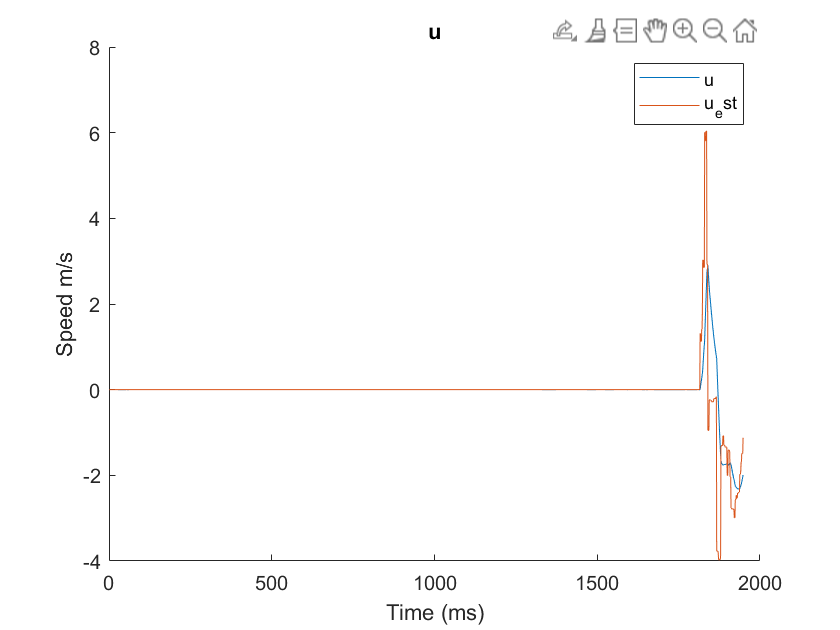


figure;
hold on;
plot(u);
plot(u_est)
xlabel("Time (ms)");
ylabel("Speed m/s");
title("u");
legend('u','u_est')
set(gcf,'Visible','on')



v = mydata.rt_v_drone.signals.values;

v = 1948×1 single column vector
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0001
   -0.0000
    0.0002
   -0.0003


v_est = mydata.rt_v_drone_est.signals.values;

v_est =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


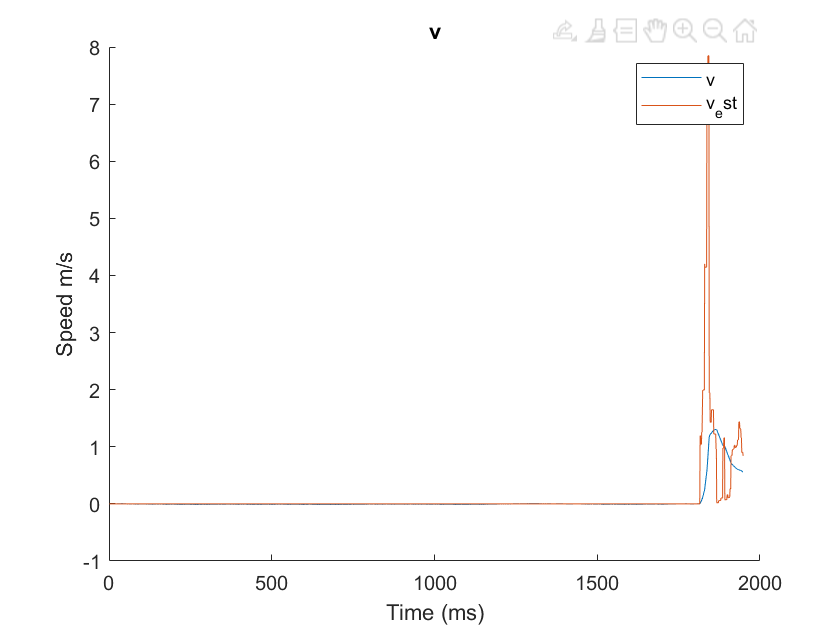


figure;
hold on;
plot(v);
plot(v_est);
xlabel("Time (ms)");
ylabel("Speed m/s");
title("v");
legend('v','v_est')
set(gcf,'Visible','on')



phi = mydata.rt_phi_drone.signals.values;

phi = 1948×1 single column vector
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0002
   -0.0001


phi_est = mydata.rt_phi_drone_est.signals.values;

phi_est = 1948×1 single column vector
    0.0015
    0.0010
    0.0000
   -0.0020
    0.0020
   -0.0210
    0.0080
    0.0605
   -0.1090
    0.0676


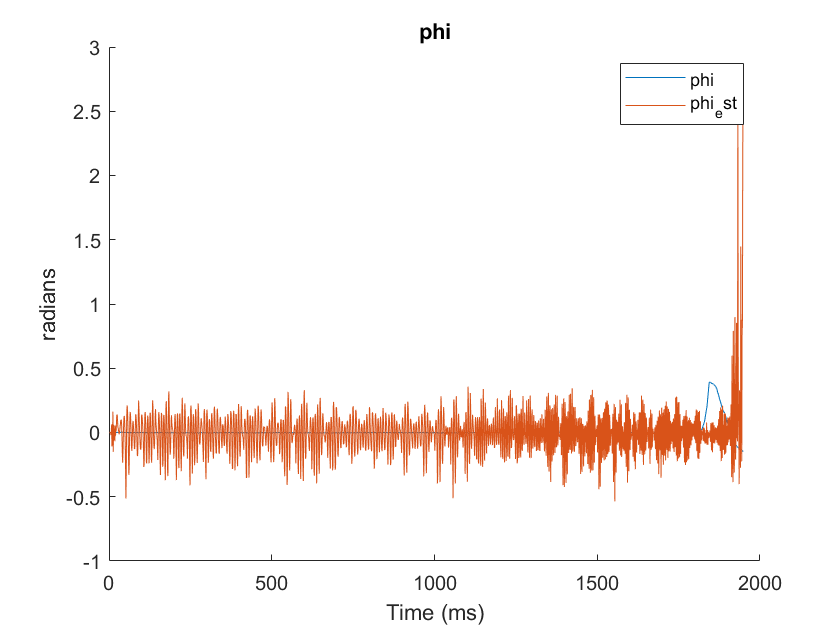

figure;
hold on;
plot(phi);
plot(phi_est)
xlabel("Time (ms)");
ylabel("radians");
title("phi");
legend('phi','phi_est')
set(gcf,'Visible','on')



theta = mydata.rt_theta_drone.signals.values;

theta = 1948×1 single column vector
         0
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0000


theta_est = mydata.rt_theta_drone_est.signals.values;

theta_est = 1948×1 single column vector
   -0.0001
    0.0003
    0.0066
    0.0043
    0.0088
    0.0036
    0.0351
   -0.0439
   -0.0086
    0.0424


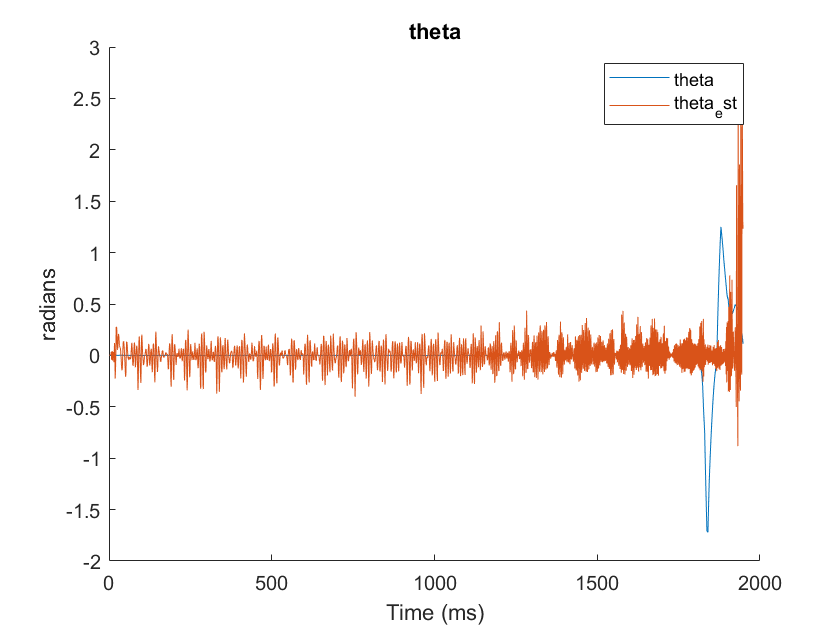

figure;
hold on;
plot(theta);
plot(theta_est)
xlabel("Time (ms)");
ylabel("radians");
title("theta");
legend('theta','theta_est')

set(gcf,'Visible','on')



Wrench = mydata.rt_Wrench.signals.values;

Wrench =     0.6664    0.0000    0.0000    0.0000
    0.6664   -0.0000   -0.0000    0.0000
    0.6664   -0.0000    0.0000    0.0000
    0.6664   -0.0000    0.0000    0.0000
    0.6663    0.0000    0.0000    0.0000
    0.6664   -0.0000    0.0000   -0.0000
    0.6667   -0.0000    0.0000    0.0000
    0.6662    0.0000   -0.0000    0.0000
    0.6665    0.0000   -0.0000   -0.0000
    0.6665   -0.0000    0.0000   -0.0000


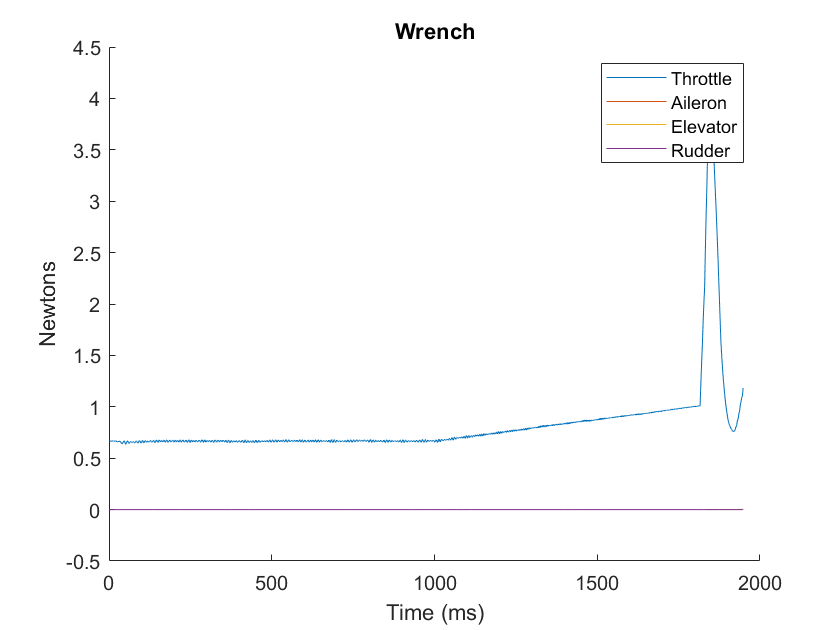

figure;
hold on;
plot(Wrench(:,1));
plot(Wrench(:,2));
plot(Wrench(:,3));
plot(Wrench(:,4));
xlabel("Time (ms)");
ylabel("Newtons");
title("Wrench");
legend('Throttle','Aileron','Elevator','Rudder')
set(gcf,'Visible','on')


Commands = mydata.rt_Commands.signals.values;

Commands =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


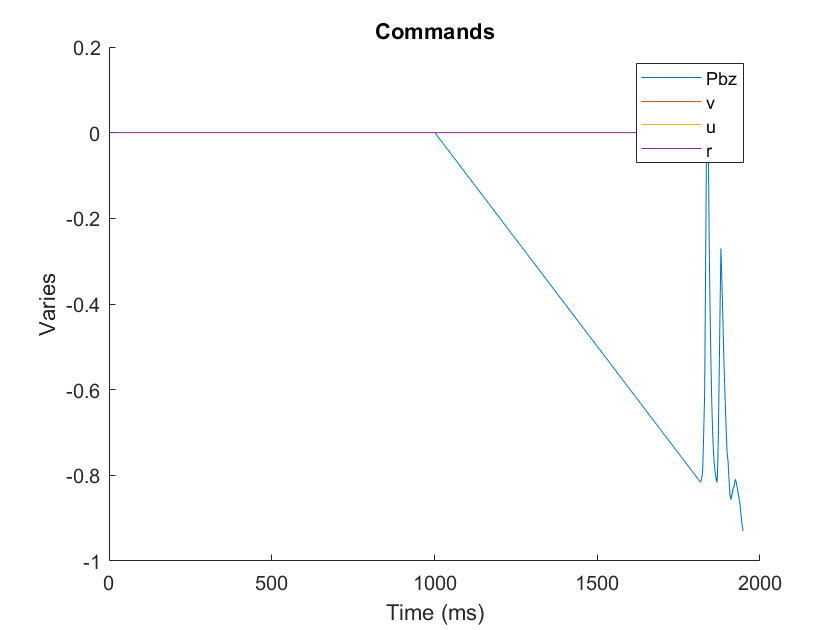

figure;
hold on;
plot(Commands(:,1));
plot(Commands(:,2));
plot(Commands(:,3));
plot(Commands(:,4));
xlabel("Time (ms)");
ylabel("Varies");
title("Commands");
legend('Pbz','v','u','r')
set(gcf,'Visible','on')


z_us = mydata.rt_z_ultrasonic.signals.values;

z_us = 1948×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


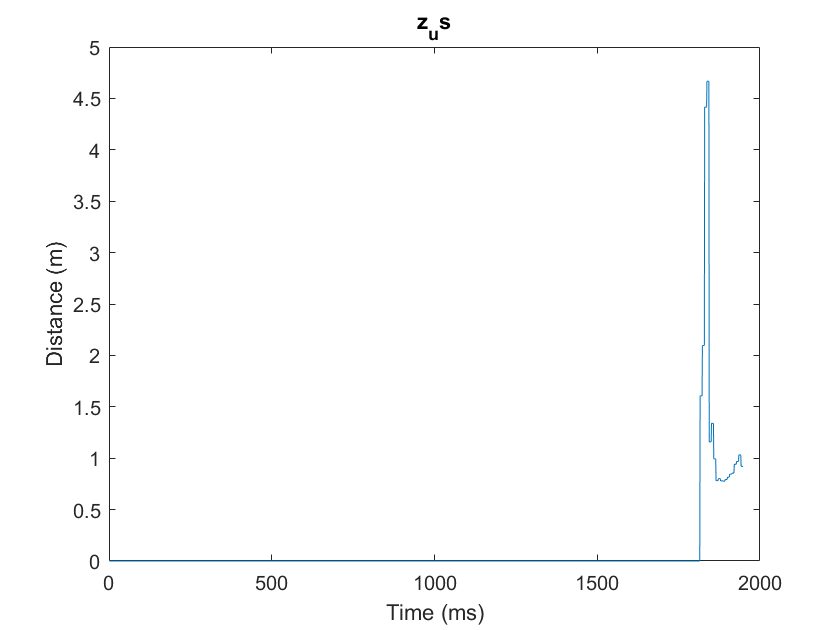

figure;
plot(z_us);
xlabel("Time (ms)");
ylabel("Distance (m)");
title("z_us");
set(gcf,'Visible','on')